s = tf('s');
F = (s+10)/(s^3 + 45*s^2 - 250*s)


F =
 
         s + 10
  --------------------
  s^3 + 45 s^2 - 250 s
 
Continuous-time transfer function.



Kr = 2

Kr = 2

a) Guadagno stazionario di F(s)

Kf = dcgain(s*F)

Kf = -0.0400

Singolarità, pulsazione e smorzamento

damp(F)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  5.00e+00    -1.00e+00       5.00e+00        -2.00e-01    
 -5.00e+01     1.00e+00       5.00e+01         2.00e-02    


zeri = zero(F)

zeri = -10

Diagrammi di Bode per la valutazione della fase

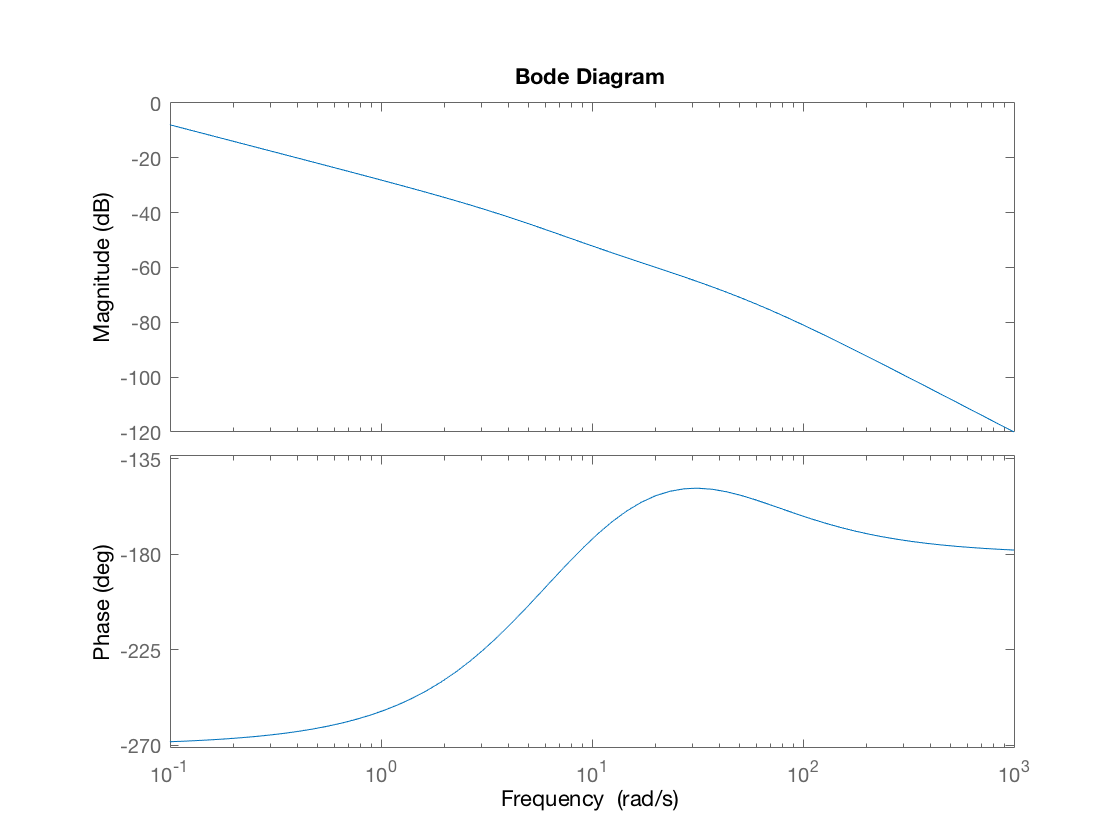

bode(F)

b)

Kc = 1

Kc = 1

Ga = Kc/Kr * F


Ga =
 
       0.5 s + 5
  --------------------
  s^3 + 45 s^2 - 250 s
 
Continuous-time transfer function.



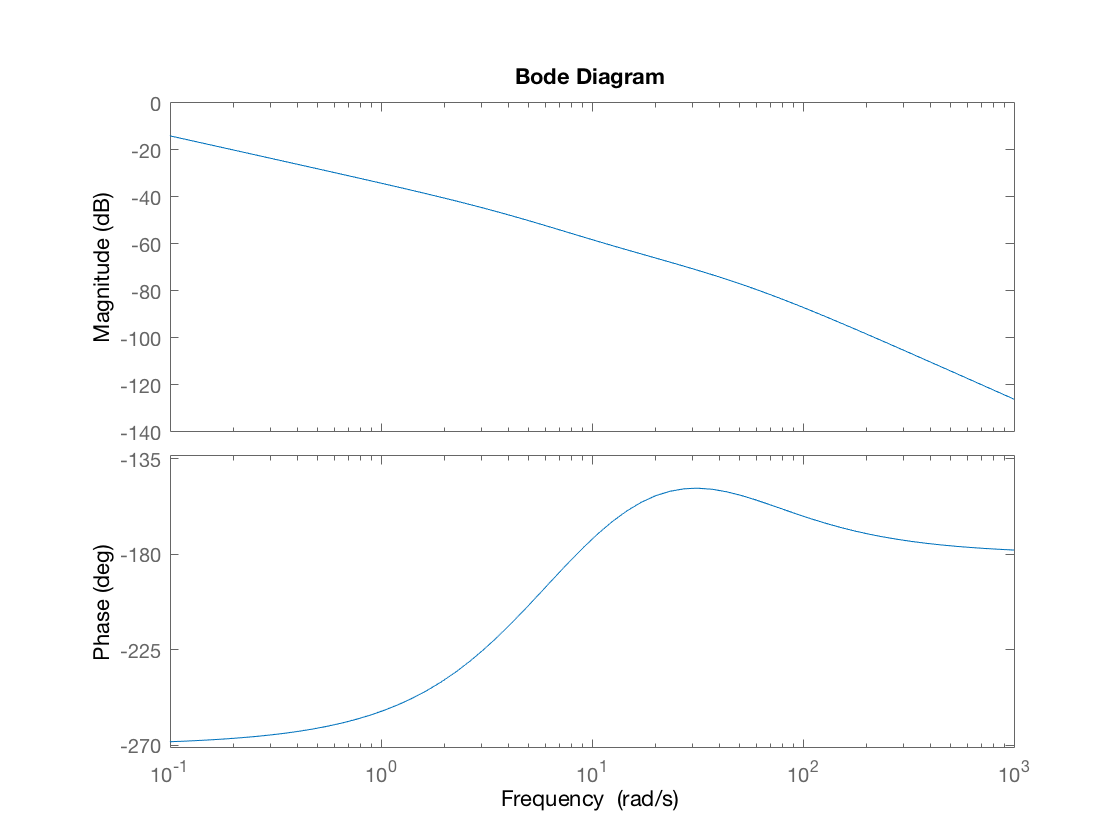

bode(Ga)

c) Diagramma di Nyquist di Ga(jw)

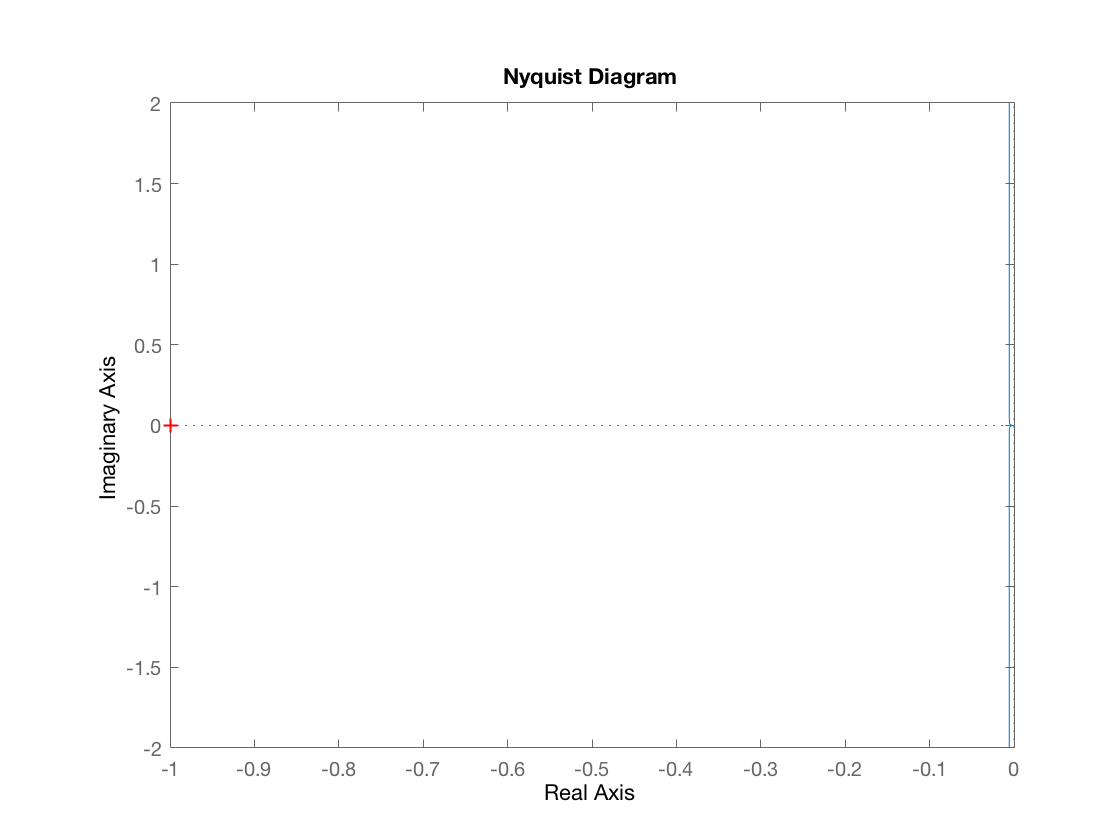

nyquist(Ga)

d) L'asse reale viene intersecato a circa -1.54

Kc_max = -1/(-1.54)

Kc_max = 0.6494

Verifica della stabilità per Kc = 800

Kc = 800

Kc = 800

Ga = Kc/Kr * F;
W = feedback(Kc*F, 1/Kr);
damp(W)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.69e-01 + 9.55e+00i     6.99e-02       9.57e+00         1.50e+00    
 -6.69e-01 - 9.55e+00i     6.99e-02       9.57e+00         1.50e+00    
 -4.37e+01                 1.00e+00       4.37e+01         2.29e-02    


e)

Funzione di trasferimento errore di inseguimento

%We = Kr*feedback(1,Ga); %feedback(1, Kc/Kr * F);
We = Kr * feedback(1, Kc/Kr * F);

Funzione di trasferimento errore dovuto a d1

We1 = feedback(F, Kc/Kr);

Funzione di trasferimento errore dovuto a d1

We2 = feedback(1, Kc/Kr * F);

e1)

r(t) = t        ->         R(s) = 1/s^2

d1 = 0.1/s


d1 =
 
  0.1
  ---
   s
 
Continuous-time transfer function.



d2 = 0.5/s


d2 =
 
  0.5
  ---
   s
 
Continuous-time transfer function.



R = 1/s^2;
e_ins = dcgain(s * We * R)

e_ins = -0.1250

e_d1 = dcgain(s * We1 * d1)

e_d1 = 2.5000e-04

e_d2 = dcgain(s * We2 * d2)

e_d2 = 0

e_tot = e_ins - e_d1 - e_d2

e_tot = -0.1253

e2)

r(t) = 2        ->          R(s) = 2/s

d1 = 0/s


d1 =
 
  0
 
Static gain.



%d2 = 0.01t
d2 = 1/(100*s^2)


d2 =
 
     1
  -------
  100 s^2
 
Continuous-time transfer function.



R = 2/s;
e_ins = dcgain(s * We * R)

e_ins = 0

e_d1 = dcgain(s * We1 * d1)

e_d1 = 0

e_d2 = dcgain(s * We2 * d2)

e_d2 = -6.2500e-04

e_tot = e_ins - e_d1 - e_d2

e_tot = 6.2500e-04